%code to train SVM model using time-series features
%load features and ground truth labels in training and testing files
newFeats = normalize(allfeats(:,3:end));
feats=newFeats(:,~isnan(newFeats{1,:}));


clc
close all
%plot ROC curve and AUC
name = ['SVM + Time-series + raw'];
[preds, scores] = tsmov.predictFcn(feats);
classNames = {'A','N','O'};
clf;
hold on
h1=figure(1)

h1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [681 559 560 420]
       Units: 'pixels'

  Show all properties


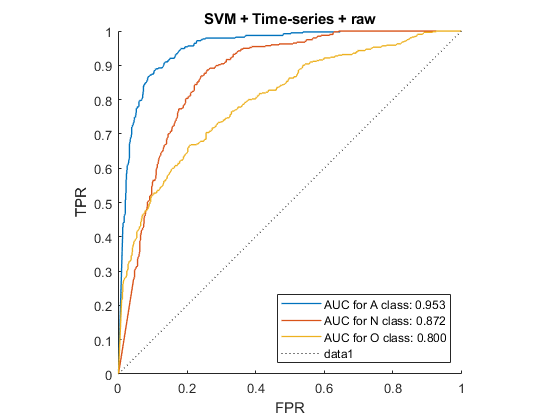

for i=1:3
    [xr, yr, ~, auc] = perfcurve(Labels,scores(:, i), classNames{i});
    plot(xr, yr, 'linewidth', 1)
    legends{i} = sprintf('AUC for %s class: %.3f', classNames{i}, auc);
end

legend(legends, 'location', 'southeast')
line([0 1], [0 1], 'linestyle', ':', 'color', 'k');
xlabel('FPR'), ylabel('TPR')
title(name)
axis square
hold off

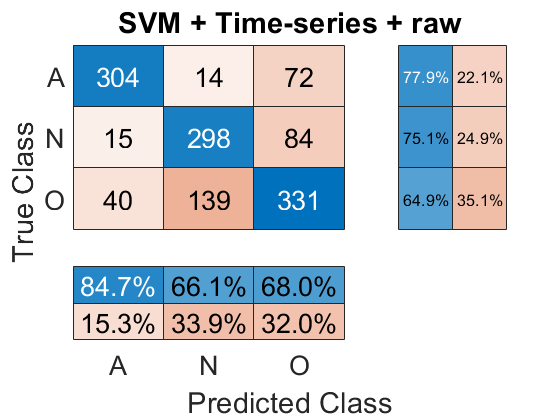

figure(2)
h2=confusionchart(Labels,preds,'ColumnSummary','column-normalized',...
              'RowSummary','row-normalized','Title',name,"FontSize",20);


%save(name,"h2","SVM_TS_raw3","feats","Labels")